# 

## MATLAB Fundamentals: Tutorial 02, Exercise 05

### August 2023

# 5.  ODE Solving and Graphics  

Consider a pendulum subject to gravity and damping, as shown in Figure 5-1.

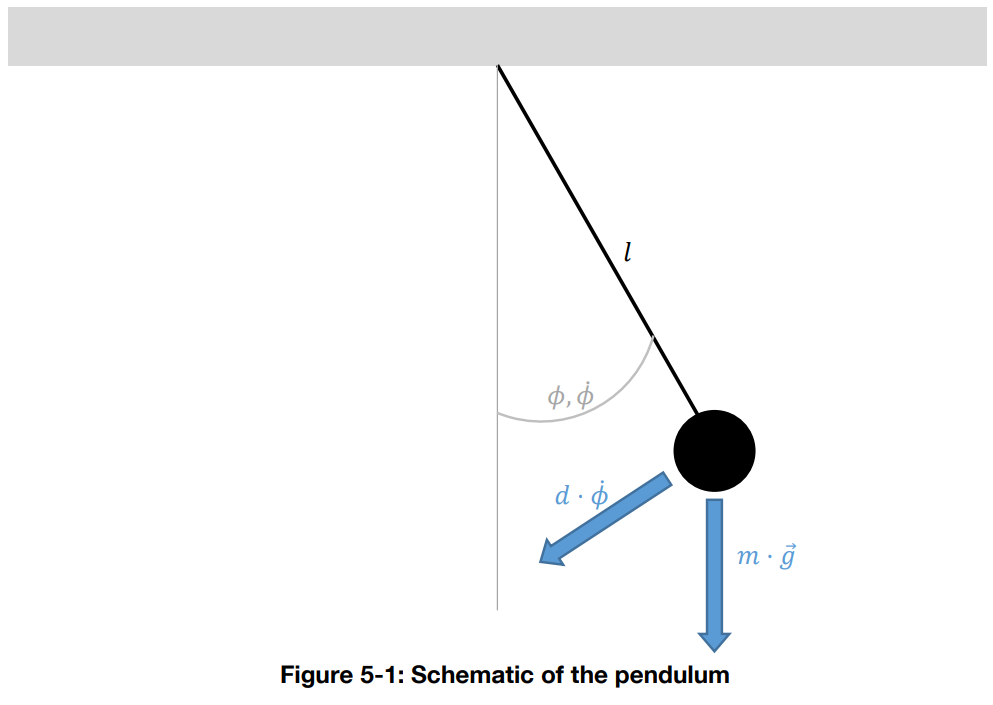

The pendulum’s nonlinear dynamics can be written as follows:


$$\ddot \phi = - \frac gl \sin\phi - \frac d {ml^2} \dot \phi$$


with the Earth’s gravitation $g$, the mass $m$, the length of the rod $l$ and a damping constant $d$. For small angles $\phi$, we can assume $\sin\phi \approx \phi$, which leads to the following linear equation:


$$\ddot \phi = - \frac gl \phi - \frac d {ml^2} \dot \phi$$


**Exercise**

(1)     Solve the linear pendulum differential equation in MATLAB symbolic language. Assume $\phi(0) = 1 \text{rad}$ and $\dot \phi(0) = 0$.

% asign all varibles of g,l,d,m,phi, and time 't'
syms phi(t) g l d m;
% equation formen using diff second order
equation = diff(phi, t, 2) == - (g/l) * phi - (d / (m * l^2)) * diff(phi, t);
% set dphi into a varible so that easier to create the condition
dphi = diff(phi,t);
% starting condition given
cond = [phi(0) == 1, dphi(0) == 0];
phi_sol = dsolve(equation, cond);

(2)    Take the solution obtained and insert the following values:

$l = 10 \text m \\ m = 5 \text{kg} \\ g = 9,81 \text{m s}^{-2} \\ d = 50 \text{kg m}^2\text{ s}^{-1}$s

% subsitute the values above to the solution using subs function
phi_subs_sol = subs(phi_sol,{g,l,d,m},{9.81,10,50,5});

(3)    Compute the pendulum angle $\phi(5\text s)$ and give a 40-digit numeric representation. Note down the first three and the last three digits.

digits(40);
phi_5s = subs(phi_subs_sol,'t',5);
phi_5s_numeric = vpa(phi_5s);

### *Hint:* Use `vpa`.

(4)    Make a 3D-plot for $t \in \left[0; 40 \right]$. Plot $l \sin \phi$ on the x-axis, $t$ on the y-axis and $-l \cos\phi$ on the z-axis.

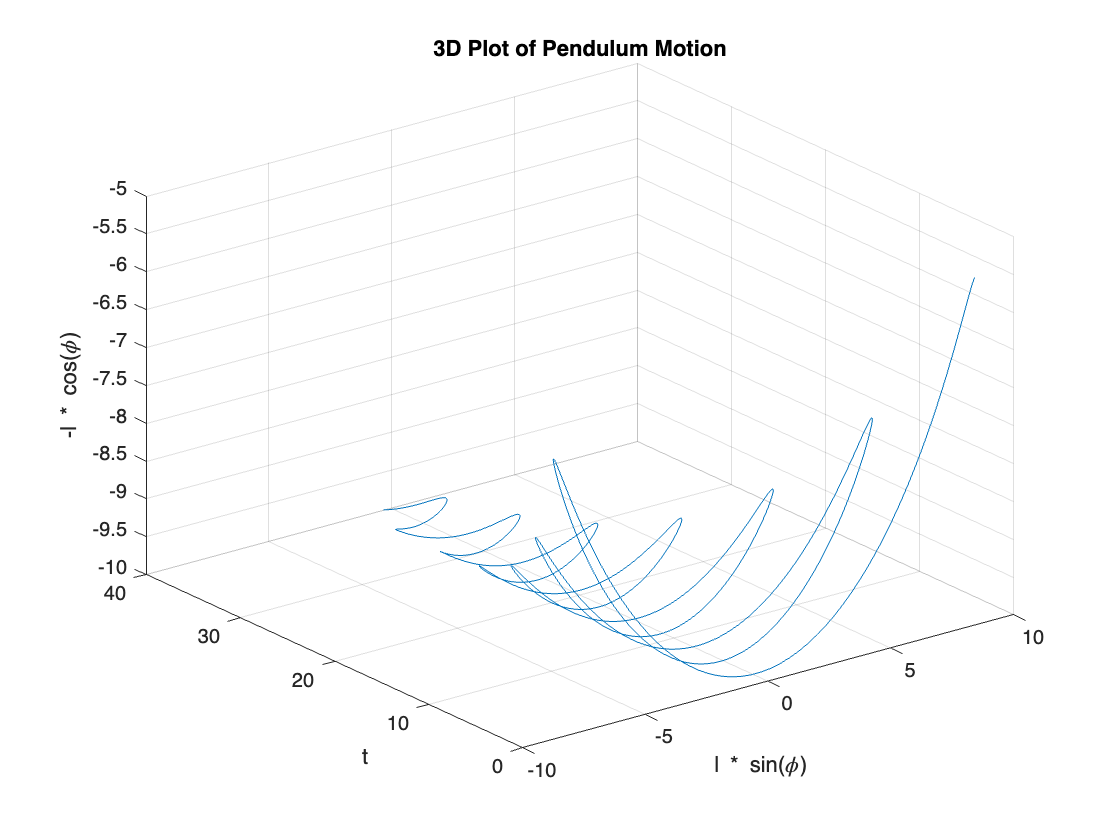

% l=10m
l_value = 10;
% t∈[0:40]
t_values = linspace(0, 40, 1000);
phi_values = double(subs(phi_subs_sol, 't', t_values));

x = l_value * sin(phi_values);
y = t_values;
z = -l_value * cos(phi_values);

figure;
plot3(x, y, z);
xlabel('l * sin(\phi)');
ylabel('t');
zlabel('-l * cos(\phi)');
title('3D Plot of Pendulum Motion');
grid on;

(5)    Look at the plot from different angles. Note that when you look along the y-axis onto the xz-plane, you can see the pendulum oscillation.

Technische Universität München – Lehrstuhl für Flugsystemdynamik – MATLAB Fundamentals: Tutorial 02 – August 2023